clear
close all
duration = 2.1;
% bfl load
load('LOG00082.mat');
bfl = table2array(LOG00082);
% bfl extract
[bfl_time, q, sp_q, accX, accY, accZ, bfl_quat] = deal((bfl(:,2)-bfl(1,2))/1e6, bfl(:,26), bfl(:,20), bfl(:,28)/2e3, bfl(:,29)/2e3, bfl(:,30)/2e3, bfl(:,31:34)/1e4);
% bfl process
q = deg2rad(q);
acc = sqrt(accX.^2+accY.^2+accZ.^2);
[bfl_pitch, bfl_roll, bfl_yaw] = quat2angle(bfl_quat, 'YXZ');
% [bfl_pitch, bfl_roll, bfl_yaw] = deal(rad2deg(bfl_pitch), rad2deg(bfl_roll), rad2deg(bfl_yaw));
% bfl cutoff
% figure; plot(bfl_time, sp_q); title("q set point用来找BFL起点")
bfl_st = 8.4532; bfl_en = bfl_st + duration;
bfl_st_bf = 21.9048; bfl_en_bf = bfl_st_bf + duration;

% rosbag load
bag = rosbag('output_2023-08-17-18-25-58.bag');
% rosbag pose extract
vehicle_pose_select = select(bag,'Time',...
    [bag.StartTime bag.EndTime],'Topic','/vrpn_client_node/jackBi/pose');
vehicle_pose_struct = readMessages(vehicle_pose_select,'DataFormat','struct');
opti_time = cellfun(@(m) double(m.Header.Stamp.Sec),vehicle_pose_struct) + ...
            cellfun(@(m) double(m.Header.Stamp.Nsec),vehicle_pose_struct)*1e-09;
opti_pos = [cellfun(@(m) double(m.Pose.Position.X),vehicle_pose_struct), ...
        -cellfun(@(m) double(m.Pose.Position.Y),vehicle_pose_struct), ...
        cellfun(@(m) double(m.Pose.Position.Z),vehicle_pose_struct)];
opti_quat = [cellfun(@(m) double(m.Pose.Orientation.W),vehicle_pose_struct), ...
            cellfun(@(m) double(m.Pose.Orientation.X),vehicle_pose_struct), ...
            cellfun(@(m) double(m.Pose.Orientation.Y),vehicle_pose_struct), ...
            cellfun(@(m) double(m.Pose.Orientation.Z),vehicle_pose_struct)];
% rosbag goal extract
goal_select = select(bag,'Time',...
    [bag.StartTime bag.EndTime],'Topic','/goal');
goal_struct = readMessages(goal_select,'DataFormat','struct');
goal_time = cellfun(@(m) double(m.Header.Stamp.Sec),goal_struct) + ...
            cellfun(@(m) double(m.Header.Stamp.Nsec),goal_struct)*1e-09;
goal_pos = [cellfun(@(m) double(m.Pose.Position.X),goal_struct), ...
            cellfun(@(m) double(m.Pose.Position.Y),goal_struct), ...
            cellfun(@(m) double(m.Pose.Position.Z),goal_struct)];
goal_pos = goal_pos(1,:)

goal_pos =          0         0    1.1000


error_pos = goal_pos - opti_pos;
% rosbag process
opti_time = opti_time - opti_time(1);
[opti_pitch, opti_roll, opti_yaw] = quat2angle(opti_quat, 'YXZ');
% [opti_pitch, opti_roll, opti_yaw] = deal(rad2deg(opti_pitch), rad2deg(opti_roll), rad2deg(opti_yaw));
% rosbag cutoff
% figure; plot(opti_time, opti_pitch); title("pitch用来找rosbag起点")
pose_st = 16.6208 - 0.1; pose_en = pose_st + duration;
pose_st_bf = 30.075 - 0.1; pose_en_bf = pose_st_bf + duration;

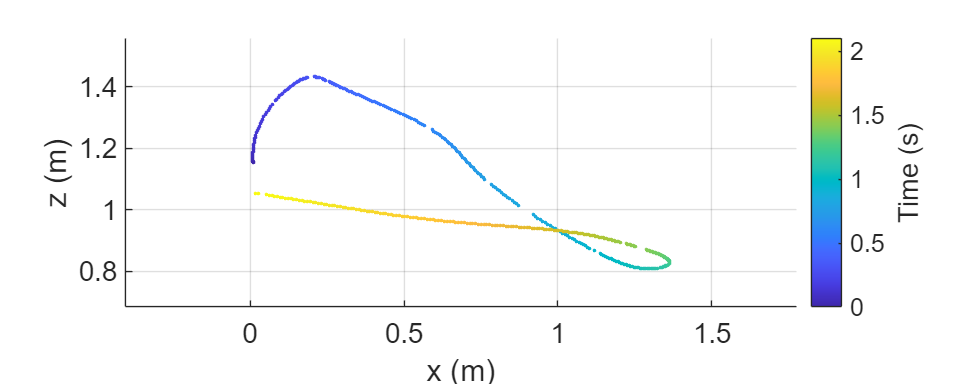

trajplot(opti_time, opti_pos, pose_st, pose_en)

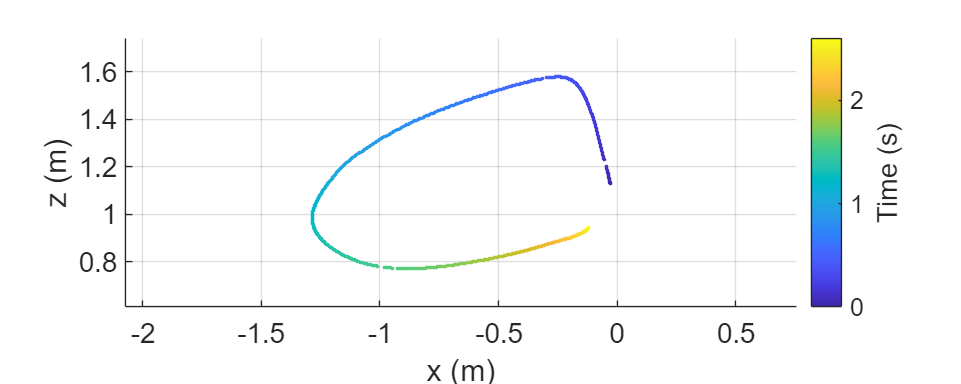

trajplot(opti_time, opti_pos, pose_st_bf, pose_en_bf + 0.5)

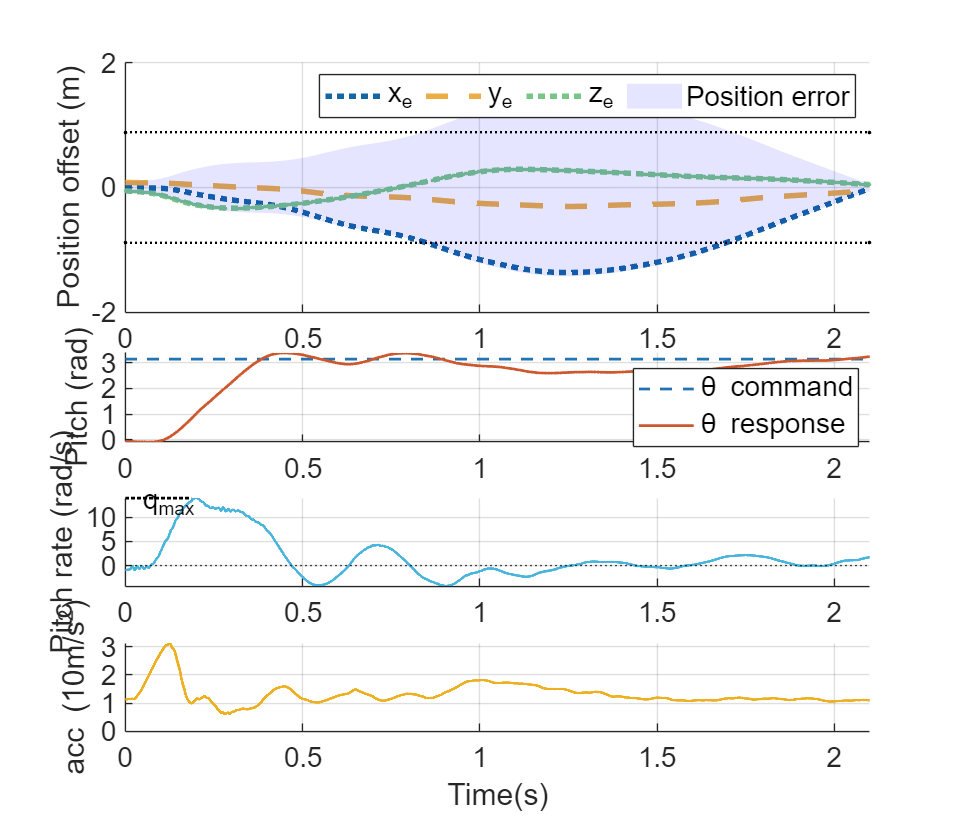

teamupplot(bfl_time, bfl_pitch, q, acc, bfl_st, bfl_en, opti_time, opti_pitch, pose_st, pose_en, error_pos, 1)

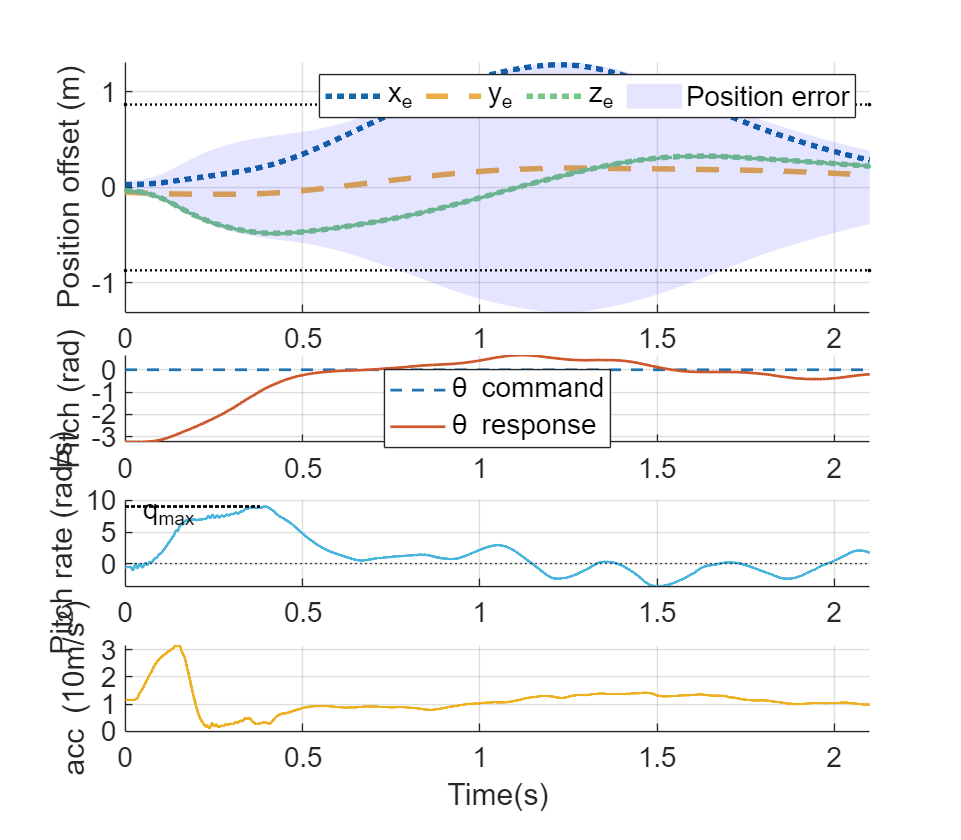

teamupplot(bfl_time, bfl_pitch, q, acc, bfl_st_bf, bfl_en_bf, opti_time, opti_pitch, pose_st_bf, pose_en_bf, error_pos, 0)

function teamupplot(bfl_time, bfl_pitch, q, acc, bfl_st, bfl_en, opti_time, opti_pitch, pose_st, pose_en, error_pos, signal)
% bfl st:en
[bfl_low, bfl_high] = deal(find(bfl_time>bfl_st, 1), find(bfl_time>bfl_en, 1));
[bfl_time, q, bfl_pitch] = deal(bfl_time(bfl_low:bfl_high)-bfl_st, q(bfl_low:bfl_high), bfl_pitch(bfl_low:bfl_high));
% bfl pitch correct
if signal == 1
bfl_pitch(bfl_pitch<-1) = bfl_pitch(bfl_pitch<-1) + 2*pi;
elseif signal == 0
bfl_pitch(bfl_pitch>1) = bfl_pitch(bfl_pitch>1) - 2*pi;
end
% qmax
[max_q, max_q_ind] = max(q); max_q_t = bfl_time(max_q_ind-1);
% rosbag st:en
[bag_low, bag_high] = deal(find(opti_time>pose_st, 1), find(opti_time>pose_en, 1));
[opti_time, opti_pitch, error_pos] = deal(opti_time(bag_low:bag_high)-opti_time(bag_low), opti_pitch(bag_low:bag_high), error_pos(bag_low:bag_high,:));
% rosbag pitch correct
if signal == 1
opti_pitch(opti_pitch<-1) = opti_pitch(opti_pitch<-1) + 2*pi;
elseif signal == 0
opti_pitch(opti_pitch>1) = opti_pitch(opti_pitch>1) - 2*pi;
end
% rosbag error
e_a = sqrt(error_pos(:,1).^2+error_pos(:,2).^2+error_pos(:,3).^2);
X_syn = [opti_time',fliplr(opti_time')];
Y_syn = [e_a',fliplr(-e_a')];
RMS_error_syn = sqrt(mse(e_a));

% Plot
figure; grid on; hold on; set(gcf,'color','white'); set(gcf,'Position',[0,40,1200,1050]); set(gca,'Position',[0.07,0.10,0.88,0.82])

subplot(5,1,[1 2]); hold on; grid on;
plot(opti_time, error_pos(:,1),':','Color','#1567a3','LineWidth',3);
plot(opti_time, error_pos(:,2),'--','Color', "#ebae46",'LineWidth',3);
plot(opti_time, error_pos(:,3),':.','Color','#78c687','LineWidth',3);
fill(X_syn,Y_syn,'b','EdgeColor','none'); alpha 0.1
plot([0,opti_time(end)],[RMS_error_syn,RMS_error_syn],':.k','LineWidth',1.3);
plot([0,opti_time(end)],[-RMS_error_syn,-RMS_error_syn],':.k','LineWidth',1.3);
ylabel('Position offset (m)'); 
legend('x_e','y_e', 'z_e', 'Position error','','','Orientation','horizontal','FontSize',15);
set(gca,'fontsize',15,'FontAngle','normal'); xlim([0 bfl_en - bfl_st]);
if max(e_a) < 1
    ylim([-1,1])
end

subplot(5,1,3); hold on; grid on;
if signal == 1
    plot([bfl_st,bfl_en]-bfl_st,[pi,pi],'--','Color','#2273b2','LineWidth',1.5); 
elseif signal == 0 
    plot([bfl_st,bfl_en]-bfl_st,[0,0],'--','Color','#2273b2','LineWidth',1.5); 
end
plot(opti_time, opti_pitch,'Color','#ce582e','LineWidth',1.5);
legend('\theta command','\theta response', 'Location','best','FontSize',15); 
% plot(bfl_time,bfl_pitch,'LineWidth',1.5); legend('\theta command','\theta response rosbag', '\theta response bfl', 'Location','best','FontSize',15); 
ylabel('Pitch (rad)');
xlim([0 bfl_en - bfl_st]);
set(gca,'fontsize',15,'FontAngle','normal');

subplot(5,1,4); hold on; grid on;
plot(bfl_time,q,'Color','#4ab5dc','LineWidth',1.5); yline(0,':k');
plot([0,max_q_t-0.012],[max_q,max_q],':k','LineWidth',1.5); text(0.04,max_q-1,'q_{max}',"FontSize",15); 
ylabel('Pitch rate (rad/s)');
set(gca,'fontsize',15,'FontAngle','normal'); xlim([0 bfl_en-bfl_st]);

subplot(5,1,5); hold on; grid on;
plot(bfl_time,acc(bfl_low:bfl_high),'Color',[0.93,0.69,0.13],'LineWidth',1.5); % '#4ab5dc'
xlabel('Time(s)'); ylabel('acc (10m/s^2)');
set(gca,'fontsize',15,'FontAngle','normal');
xlim([0 bfl_en-bfl_st]);
set(gca,'YTick',[0,1,2,3])
end
% % set(gca,'YTick',[0,1,2,3,pi,4])
% ylim([min(opti_pitch)-0.1,4])
%text(0.005,max_q+50,[num2str(roundn(max_q,-2))],"FontSize",20);

function trajplot(opti_time, opti_pose, pose_st, pose_en)
[bag_low, bag_high] = deal(find(opti_time>pose_st, 1), find(opti_time>pose_en, 1));
[pose_x, pose_z] = deal(opti_pose(bag_low:bag_high,1), opti_pose(bag_low:bag_high,3));

figure; hold on;grid on;
scatter(pose_x, pose_z,4,linspace(0, pose_en-pose_st, bag_high-bag_low+1),'filled');
c = colorbar; c.Label.String = 'Time (s)'; c.Label.FontSize = 15;
xlabel('x (m)');ylabel('z (m)');
set(gcf,'Position',[0,40,1000,400]); set(gca,'Position',[0.13,0.2,0.70,0.7]); set(gca,'fontsize',15,'FontAngle','normal');
axis equal; ylim([min(pose_z)-0.2*range(pose_z), max(pose_z)+0.2*range(pose_z)])
% xlim([min(pose_x)-0.2*range(pose_x), max(pose_x)+0.2*range(pose_x)]);
end
